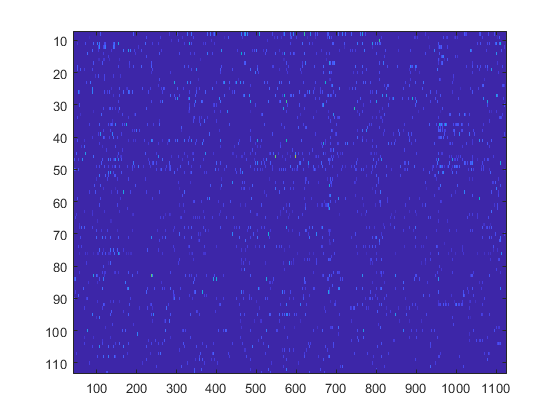

% bin by 1 s
fr = 15;
twindow = 1; % in seconds
mlen = min(size(xz83.FFTTraces,1), size(xz85.FFTTraces,1));
mlen = mlen - mod(mlen, fr*twindow);
s83 = xz83.S(:,1:mlen);
s85 = xz85.S(:,1:mlen);
s83bin = [];
s85bin = [];
for i = 1:twindow*fr:mlen
    s83bin = [s83bin, sum(s83(:,i:(i+twindow*fr-1)), 2)];
    s85bin = [s85bin, sum(s85(:,i:(i+twindow*fr-1)), 2)];
end
figure, imagesc(s83bin);

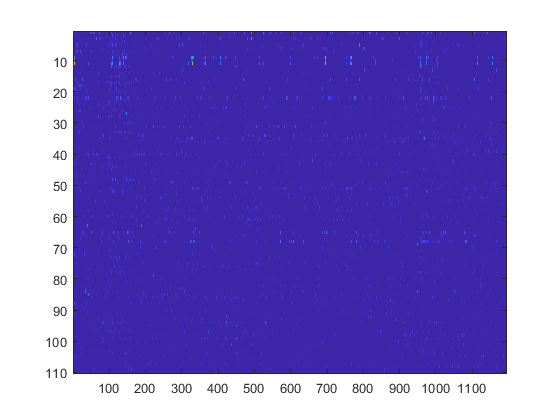

figure, imagesc(s85bin);

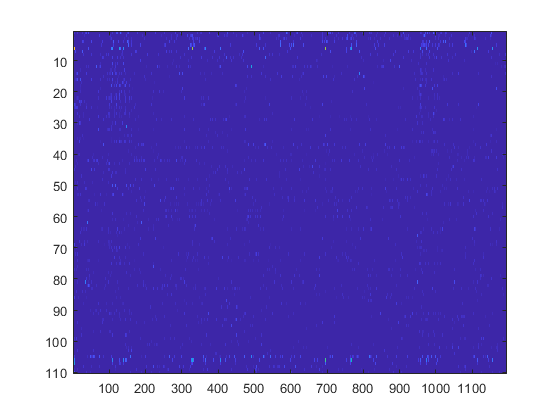

[idx, centro, sumd] = kmeans(s85bin, 10);
[id1, id2] = sort(idx);
figure, imagesc(s85bin(id2,:));

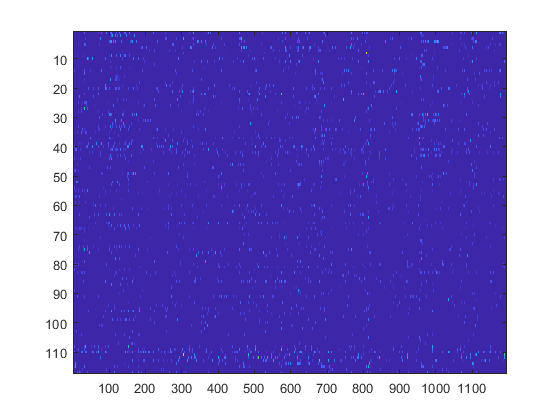

[idx, centro, sumd] = kmeans(s83bin, 10);
[id1, id2] = sort(idx);
figure, imagesc(s83bin(id2,:));

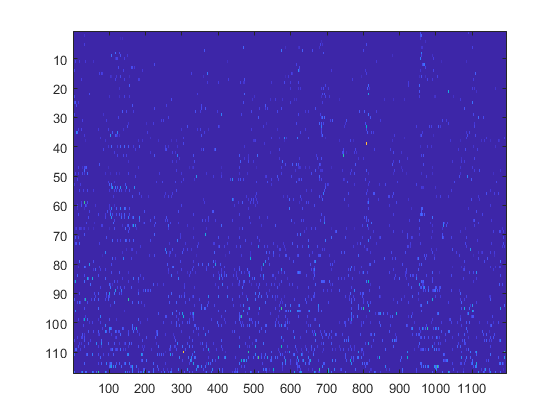

[~,idx83] = sort(sum(s83bin,2));
[~,idx85] = sort(sum(s85bin,2));
figure, imagesc(s83bin(idx83,:));

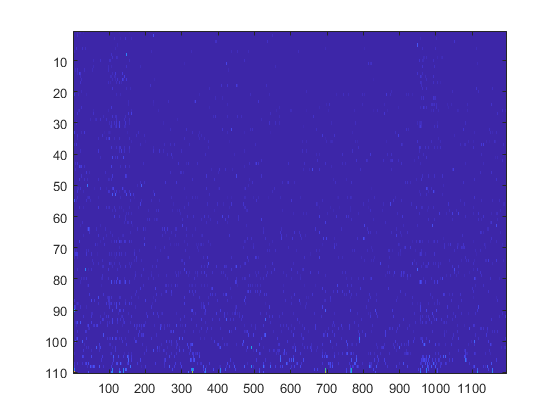

figure, imagesc(s85bin(idx85,:));

corr(mean(zscore(xz83.FiltTraces(1:17932,idx83(1:25))),2),mean(zscore(xz85.FiltTraces(:,idx85(1:25))),2))

ans = 0.5826

PlotSelectedCells(xz83, idx83(76:100))
PlotSelectedCells(xz85, idx85(76:100))